Illustrate encoding and decoding of a BCH product code on the BSC.

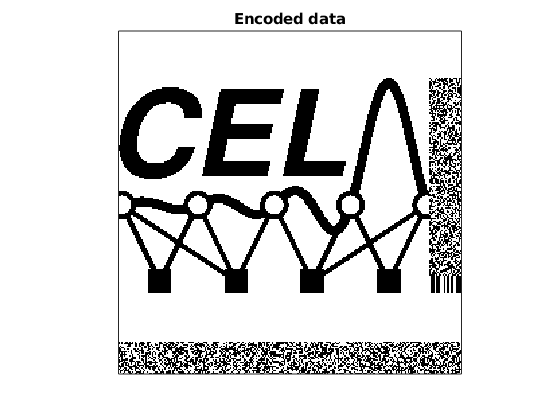

data = gf(imread('LogoCEL.png'));
if size(data,1) ~= 231 && size(data,2) ~= 231
    error('Size of image must be 231x231');
end

% horizontal encoding
data_henc = bchenc(data, 255, 231);

% vertical encoding
data_enc = bchenc(data_henc', 255, 231)';

% display
figure;
imagesc(double(data_enc.x)); colormap gray; axis square; set(gca, 'Xtick',[]); set(gca, 'YTick',[])
title('Encoded data')

Carry out the decoding. Here, we have a code of rate $r=\left(\frac{231}{255}\right)^2 \approx 0.8206$. According to the channel coding theorem, the largest $\delta$ at which decoding is possible is $\approx 0.0271$. Hence, we vary $\delta$ within this region and show the performance. You can try yourself at what $\delta$ the code will still be able to decode (almost) error-free.

% add noise
delta = 0.0154

delta = 0.0154

decoding_iterations = 19

decoding_iterations = 19

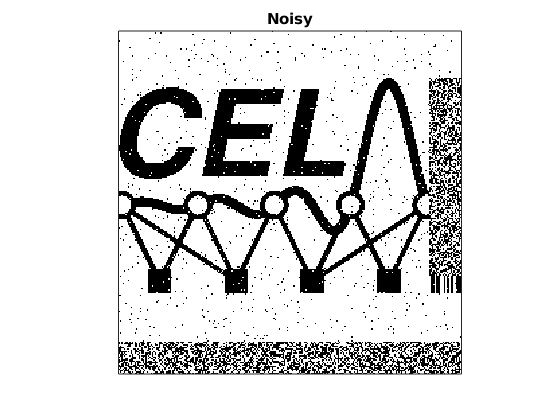

noise = gf(rand(size(data_enc)) < delta);
received = data_enc + noise;
% display
figure;
imagesc(double(received.x)); colormap gray; axis square; set(gca, 'Xtick',[]); set(gca, 'YTick',[])
title('Noisy')

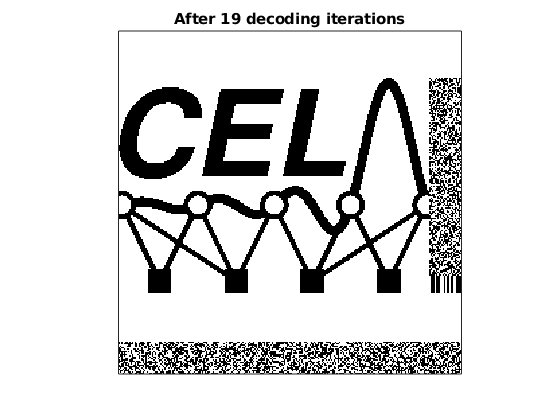


% carry out decoding iterations
decoded = received;
for iter = 1:decoding_iterations
    % vertical decoding
    [~,~,decoded] = bchdec(decoded', 255, 231);
    decoded = decoded';
    % horizontal decoding
    [~,~,decoded] = bchdec(decoded, 255, 231);
end
figure;
imagesc(double(decoded.x)); colormap gray; axis square; set(gca, 'Xtick',[]); set(gca, 'YTick',[])
title(sprintf('After %d decoding iterations', decoding_iterations));